p1 = rand([3 1])*10;
p2 = rand([3 1])*10;
k = rand([3 1]);
k = k/norm(k);
theta = rand*2*pi-pi

theta = 2.9466


d = norm(p2-rot(k,theta)*p1);

norm(p2-rot(k,theta)*p1) - d

ans = 0


t_a = fixed_subproblem3(p1,p2,k,d)

t_a =     2.9466
   -2.9074


wrapToPi(t_a)

ans =     2.9466
   -2.9074



norm(p2-rot(k,t_a(1))*p1) - d

ans = 8.8818e-16

norm(p2-rot(k,t_a(2))*p1) - d

ans = 0

t_b = subproblem3_linear(p1,p2,k,d)

t_b =    -2.9074    2.9466



norm(p2-rot(k,t_b(1))*p1) - d

ans = 0

norm(p2-rot(k,t_b(2))*p1) - d

ans = 8.8818e-16

sp3_error(p1, p2, k, d, t_b(1))

ans = 0

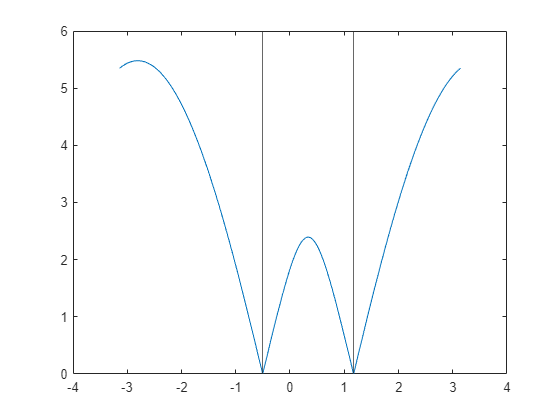

p1 = rand([3 1])*10;
p2 = rand([3 1])*10;
k = rand([3 1]);
k = k/norm(k);
d = abs(rand*10);

t = subproblem3_linear(p1,p2,k,d);

t_test = linspace(-pi, pi, 1000);
e_test = NaN(size(t_test));
for i = 1:length(t_test)
    e_test(i) = sp3_error(p1, p2, k, d, t_test(i));
end

plot(t_test, e_test);
xline(t(1));
if numel(t)>1
    xline(t(2));
end

function e = sp3_error(p1, p2, k, d, theta)
    e = abs( norm(p2-rot(k,theta)*p1) - d );
end